# Q2.2 Serial implementation of GMRES.

%% Function: Arnoldi Iteration
function [Q, H] = arnoldi(A, b, m)
% input: 
%       A: The square matrix to be processed
%       b: Initial vector (I used a random number between 0 and 1 to test)
%       m: Number of iterations (that is, how many Krylov subspace vectors
%       to construct)
% output:
%       Q: Matrix containing an orthogonal basis (size n*(m+1))
%       H: Upper Hessenberg matrx (size (m+1)*m)   

n = length(A);     %get dimmension of matrix A (Assume A is a square matrix)
Q = zeros(n, m+1); %Initialize matrice Q and H are zero matrices
H = zeros(m+1, m);
    
Q(:,1) = b / norm(b);    % The initial vector u is normalized and stored as the first column of Q (q1)(this is the first step of constructing Krylov subspace),also 
    
for k = 1:m
    v = A * Q(:,k); % get a new vector
        
        % Gram-Schmidt orthogonalization
        for j = 1:k
            H(j,k) = Q(:,j)' * v;    %calculate the projection
            v = v - H(j,k) * Q(:,j);   % subtracted by projections
        end        
        
        H(k+1, k) = norm(v);         % Calculate the new element of the Hessenberg matrix
        
        % Normalize the new orthogonal basis
        if H(k+1, k) > 1e-10 
            Q(:,k+1) = v / H(k+1, k);
        else
            break; % break the iteration
        end
    end
end

%% Function: GMRES Algorithm in Serial 
function [x, R] = gmres_serial(A, b, m)
% input: 
%       A:The coefficient matrix in the equation Ax=b.It's size is n by n
%       b: The right-hand side vector of the linear system of Ax=b
%       m: Number of iterations (that is, how many Krylov subspace vectors
%       to construct)
% output:
%       x: The approximate solution to the linear system Ax=b obtained through the GMRES algorithm.
%       R: Residuals   
    n = length(b);
    x_0 = zeros(n,1); %Initialize the first solution x is a zeros vector
    r_0 = b - A*x_0;   %The first residual is r_0
    beta = norm(r_0);
    
    [Q, H] = arnoldi(A, r_0, m);  % Call the Arnoldi iteration function to get orthonogal basis Q and upper Hessenberg matrix H
    
    e1 = zeros(m+1,1);   % Construct e1=(1,0,0,...,0)^(*) 
    e1(1) = beta;  %let the first element of e1 is the norm of r_0  
    y = H \ e1;           % Least squares problem: min || H * y - beta * e1 ||
    x = x_0 + Q(:,1:m) * y;    % The final solution estimate x
    
    % history of residual norms
    R = zeros(m+1,1);
    R(1) = norm(r_0) / norm(b);

    for k = 1:m
        rk = b - A * (x_0 + Q(:,1:k) * (H(1:k+1,1:k) \ e1(1:k+1)));  %find the the residual of kth step
        R(k) = norm(rk) / norm(b);  % the final result form which what we want
        R(k+1)= norm (rk)/norm(b);
    end
end

%% Application: Run GMRES for different values of n
n_values = [8, 16, 32, 64, 128, 256];  
colors = lines(length(n_values));

figure;                         % setting for the plot
hold on;
title('GMRES Convergence for Different n');
xlabel('Iteration m');
ylabel(' Residual ||r_k|| / ||b||');
set(gca, 'YScale', 'log');           %Using semi-log graph

fid = fopen('GMRES_results.txt','w');     % Write the approximate result x and residual histories for different n in one file
if fid==-1                                % To check if opening the file successfully
    error('Cannot open filr for writing results');
end

time_record = zeros(size(n_values)); % recording runing time for each n

for i = 1:length(n_values)
    n = n_values(i);
    m = n / 2;          % Defne the number of tatol iterations
    
    % Construct tridiagonal matrix A
   e = ones(n,1);
   A = spdiags([e -4*e e], -1:1, n, n);
    

    b = (1:n)' / n;  % Construct right-hand side b
    
    tic; %timing stars

    [x, residuals] = gmres_serial(A, b, m);   % Run GMRES
    
    elapsed_time=toc; %timing end
    time_record(i) = elapsed_time % recording the time

    % Plot relative residuals
    plot(0:m, residuals, '-o', 'DisplayName', ['n = ', num2str(n)], 'Color', colors(i,:));
     
    % Write the results into the file
    fprintf(fid, '----------------------------------------------\n');
    fprintf(fid, 'n = %d, m = %d\n', n, m);
    fprintf(fid, 'CPU Time (seconds)= %.6f\n', elapsed_time);
    fprintf(fid, 'Estimated solution x:\n');
    fprintf(fid, '%f\n', x);
    fprintf(fid, 'Residual record (||r_k|| / ||b||):\n');
    fprintf(fid, '%f\n', residuals);
    fprintf(fid, '\n');        
end

time_record =     0.0029         0         0         0         0         0


time_record =     0.0029    0.0008         0         0         0         0


time_record =     0.0029    0.0008    0.0013         0         0         0


time_record =     0.0029    0.0008    0.0013    0.0014         0         0


time_record =     0.0029    0.0008    0.0013    0.0014    0.0063         0


time_record =     0.0029    0.0008    0.0013    0.0014    0.0063    0.0467



fclose (fid);  % Close the file

legend show;
hold off;
grid on;

n256Line = findobj(gcf, "DisplayName", "n = 256")

n256Line =   Line (n = 256) with properties:

              Color: [0.3010 0.7450 0.9330]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 … ] (1×129 double)
              YData: [0.0535 0.0130 0.0034 9.2268e-04 2.4720e-04 6.6233e-05 1.7746e-05 4.7549e-06 1.2740e-06 3.4136e-07 9.1462e-08 2.4506e-08 6.5661e-09 1.7593e-09 4.7139e-10 1.2630e-10 3.3841e-11 9.0672e-12 2.4294e-12 6.5092e-13 … ] (1×129 double)

  Show 

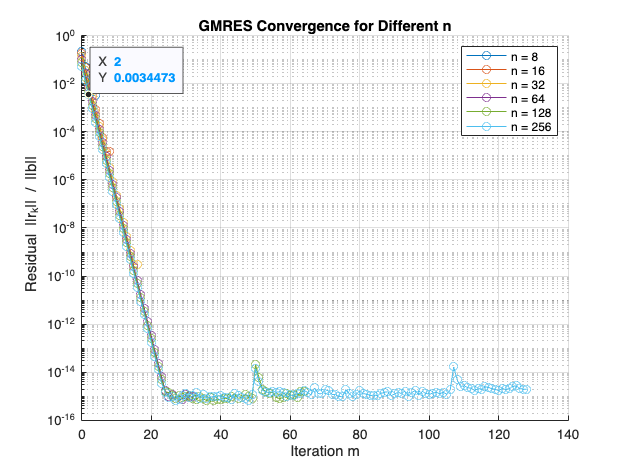

datatip(n256Line,2,0.003447);

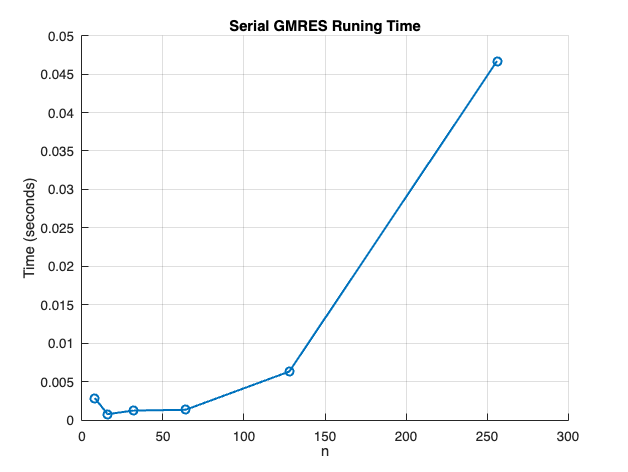



%% Plot CPU runing time
figure;
hold on;
title('CPU Time vs Problem Size');
plot(n_values, time_record, '-o','LineWidth',1.5);
title('Serial GMRES Runing Time');
xlabel('n');
ylabel('Time (seconds)');
hold off;
grid on;